clear

image_width = 162; %2 for preambule
image_height = 120;
packet_count = 3000;

file_received = fopen('lepton_data_3000_2.txt','r');
formatSpec = ['%d,'];
%for i = 1:length(received_data)
    received_data = fscanf(file_received,formatSpec, [1 inf]);
%end
fclose(file_received);


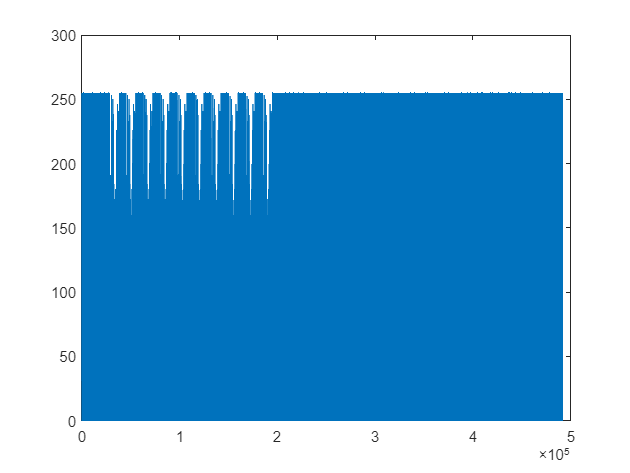

plot(received_data)

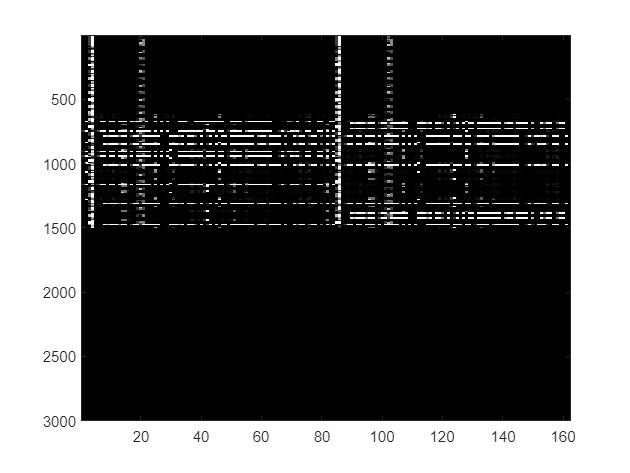

video_data = zeros(packet_count, image_width);
for line = 1:packet_count/2 - 1
    for collumn = 1:image_width-1
        x = collumn - 1;
        y = line - 1;
        idx = x*2 + y * 164*2 + 1;
        temp_data = received_data(idx)*256 + received_data(idx + 1);
        video_data(line, collumn) = temp_data;
    end
end

cropped_image = video_data(1300:1500, 1:image_width);
figure;
colormap(gray(65535));
image(video_data);

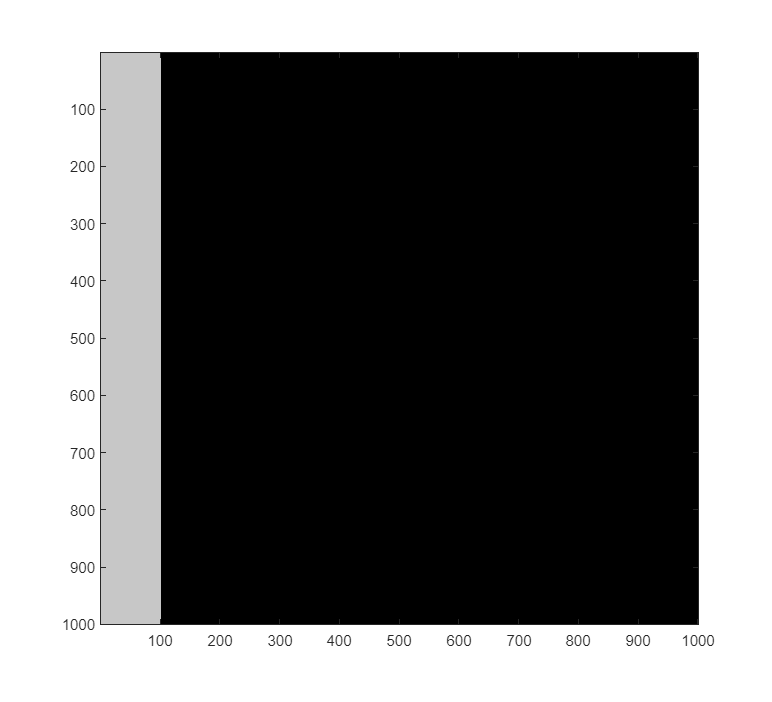

debug = zeros(1000, 1000);
debug(1:1000, 1:100) = 200;
colormap(gray(256)); image(debug);